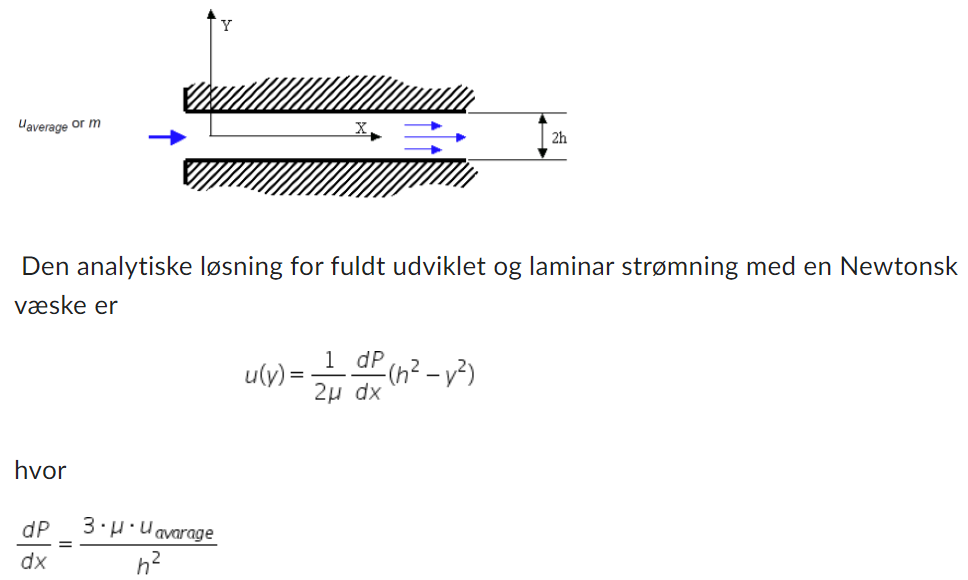

% Step size
stepSize = 0.0005;

% Number of steps on one side (excluding the middle 0)
numStepsOneSide = (21 - 1) / 2;

% Calculate the start and end values based on the number of steps and step size
startValue = -numStepsOneSide * stepSize;
endValue = numStepsOneSide * stepSize;

% Create the array
array = linspace(startValue, endValue, 21)

array =    -0.0050   -0.0045   -0.0040   -0.0035   -0.0030   -0.0025   -0.0020   -0.0015   -0.0010   -0.0005         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050




u_avg = 0.1; %m/s    
y = array%0.01-0.0005*11:0.0005:0.01+0.0005*11 %afstand fra origo i y-retningen

y =    -0.0050   -0.0045   -0.0040   -0.0035   -0.0030   -0.0025   -0.0020   -0.0015   -0.0010   -0.0005         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050


h = 0.01; %m
mu = 0.0010014; %Pa*s

u = 1/(2*mu) * (3*mu*u_avg / h^2) .* (h^2 - y.^2)

u =     0.1125    0.1196    0.1260    0.1316    0.1365    0.1406    0.1440    0.1466    0.1485    0.1496    0.1500    0.1496    0.1485    0.1466    0.1440    0.1406    0.1365    0.1316    0.1260    0.1196    0.1125


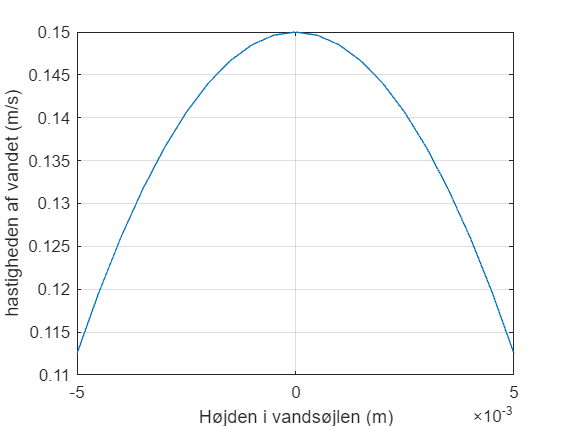


plot(y,u)
grid()%"minor"
xlabel("Højden i vandsøjlen (m)")
ylabel("hastigheden af vandet (m/s)")